Formatting the data

contNeuron = contNeuron';
respNeuron = respNeuron';

Plotting the data and formatting the graph

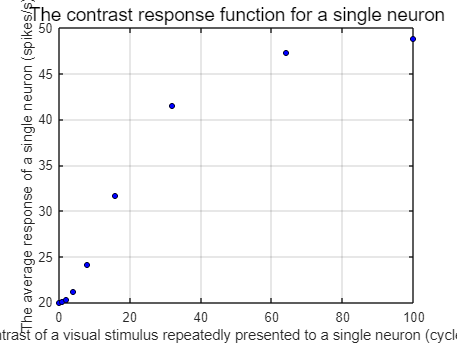

plot(contNeuron,respNeuron,"ro", "MarkerSize", 4, "MarkerFaceColor", "b", "MarkerEdgeColor", "k")
grid on
title("The contrast response function for a single neuron", "FontSize",14,"FontWeight","normal")
ylabel("The average response of a single neuron (spikes/s)", "FontSize",11)
xlabel("The contrast of a visual stimulus repeatedly presented to a single neuron (cycles/degree)", "FontSize",11)  

Determining whether the data is significant

[R,P] = corrcoef(contNeuron,respNeuron)

R =     1.0000    0.9238
    0.9238    1.0000


P =     1.0000    0.0004
    0.0004    1.0000


The p value 0.0004 < 0.05 therefore the corresponding R value, or correlation coefficient (0.9238) can be considered significant. This indicates that contrast of a visual stimulus significantly affects the response of a single neuron.

Parameterisation - The relationship here appears to be logarithmic (would have to explore MATLAB functions more) - we can see a rapid increase in spiking rate from this neuron as the contrast initially increases, however at higher contrasts the difference in spiking rate is not as prominent, and the response appears to be coming to a plateau. 